# Ballbot robust stability analysis and validation script

**Contents:**

- Nonlinear model synthesis with distrubances

- Parametric linearisation 

- Parametric uncertainty introduction

- optimisation based worst case search

- Disturbance rejection and noise attenutation

- H-infinity controller synthesis

- based on linear systems 

- based on worst case system

- Comparison of behavior with nonlinear model

clear all
mkdir('generated')
addpath('./generated')
addpath('./visualisation')
addpath('./optimisation')

## Model physical parameters definition

Introducing the physical parameters of the system

global rK_n rW_n  rA_n  l_n  mAW_n mK_n  A_ThetaAWx_n  A_ThetaAWy_n  A_ThetaAWz_n  ThetaKi_n  ThetaWi_n;

% Uncertain parameters
rK_n = 0.120; % radius of the ball
rW_n = 0.05; % radius of omni wheel=5cm
rA_n = 0.126; % radius of the body  
l_n = 0.22634; % distance between centre of ball and centre of gravity of the body 
mAW_n = 6.71; % mass of the body and omni wheel  
mK_n = 0.625; % mass of the basket ball  
A_ThetaAWx_n = 1.41271413; % Inertia of the body and Omni wheels in the body reference frame A  
A_ThetaAWy_n = 1.41271311;
A_ThetaAWz_n = 0.05359646;
ThetaKi_n = 0.003606375;
ThetaWi_n = 0.01504; 

% Angle of motors
alpha = 47*pi/180;
beta1 = 0;
beta2 = 2/3*pi;
beta3 = 4/3*pi;

% vector of nominal parameters
params_n = [rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n];

## Derivation script of the nonlinear model

Modeling ot the nonlinear system - extended matlab version of the script FInal.nb made in Mathematica

- Parametric nonlinear model creation

- Linearization around 0

- Creation of simulation functions for further analyisis - linear and nonlinear

Execution can take 5-10 minutes

model_generation;

Model physical parameters
Coordinate system transformations
Binding equations


Energies
Non-potential forces
Lagrange


Elapsed time is 4.453903 seconds.
Linear equation solving
Elapsed time is 7.821642 seconds.
State space representation
Elapsed time is 66.890140 seconds.
Creating a matlab function from nonlinear model
This may take few minutes
Elapsed time is 66.241277 seconds.
Adding linearisation point
Linearisation x0
A matrix
10/10
Elapsed time is 34.415561 seconds.
B matrix
Elapsed time is 4.589350 seconds.
W matrix
Elapsed time is 1.876028 seconds.
Create A and B and W parametric functions - physical parameters
Elapsed time is 22.883916 seconds.
Model script done


## Linear nominal model sysnthesys

Creation of linear transfer funciton based on linearised matrices of the Ballbot and the nominal parameters

Additionally the LQR controller is provided (based on the LQR controller in the report) as a default controller to be compared in further analysis.


% A matrix
tic
A_n= fA(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
fprintf('A matrix :  %f sec\n',toc);

A matrix :  0.400581 sec


% B matrix
tic
B_n= fB(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
fprintf('B matrix :  %f sec\n',toc);

B matrix :  1.027539 sec


% B_w matrix
tic
B_w= fW(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
fprintf('B_w matrix :  %f sec\n',toc);

B_w matrix :  0.412283 sec



% state space model from matrices
G_n = ss(A_n, B_n, eye(10), zeros(10,3));


LQR controller synthesis


% LQR controller design
Q = diag([100 50 100 50 40 20 20 10 20 10]);
R = diag([100 100 100]);
K_lqr = lqr(G_n,Q,R);

## Linear and nonlinear model initial condition response comparison

Finally, simple graph of initial condition response for linear and nonlinear system with nominal parameters to see how well does the lienarized system corespond with the nonlinear

nonlinear system simulation
Nonlinear simulation: 4.00 sec / 4.00 sec
Elapsed time is 36.545862 seconds.
lienar system simulation
Elapsed time is 0.771285 seconds.


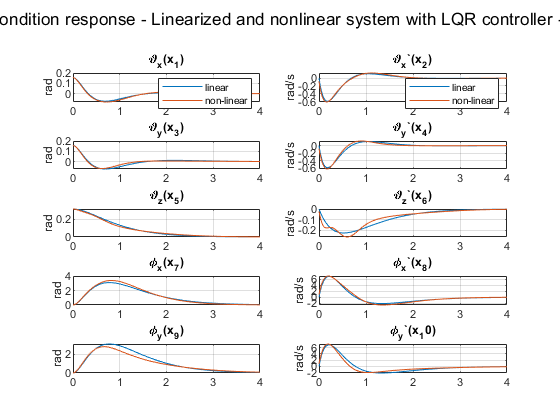

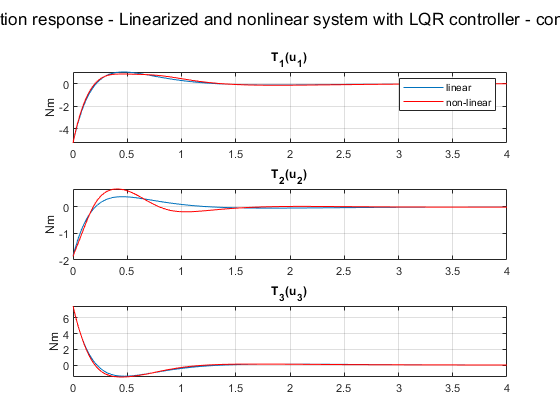

X0 = [pi/20 0 pi/20 0 pi/10 0 0 0 0 0]';
T_max = 4; %s
initialplot_compare_nlin(@nlin_model_n,G_n,K_lqr,X0,T_max,1,2)

drawnow

## Introducing the uncertainties

The uncertainties are introduced into the physiscal parameters of the system. The idea is that for the variables you cannot measure you should have some uncertainty about their values. 

The uncertainties are set as the percentage.For example if l_var is 20, that means that your height of center of mass can be +-20% different than your nominal value.

Sample uncertain models
Uncertain model visualisation - initial condition response
It may take few minutes


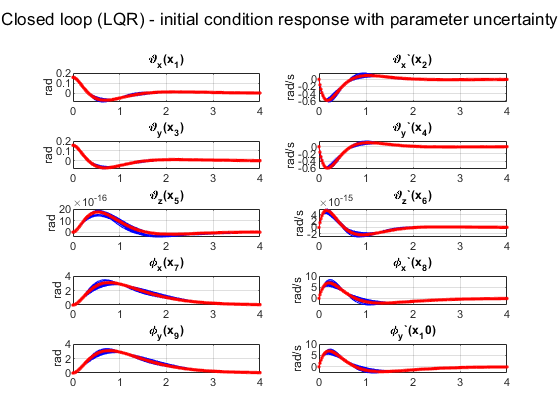

Elapsed time is 13.544083 seconds.
Uncertain model visualisation - singular value plot
It may take few minutes


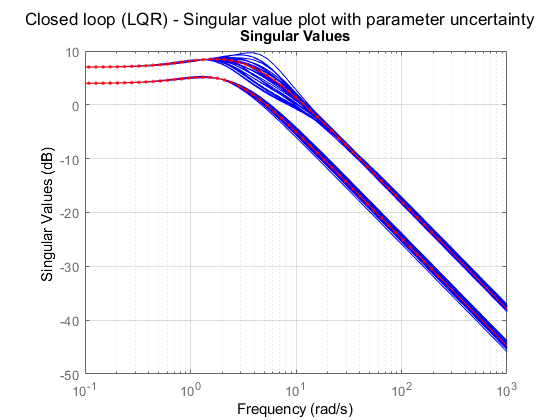

Elapsed time is 20.936281 seconds.


% Uncertain variation of the parameters
A_ThetaAWx_var = 15; % percent
l_var = 10; % percent
A_ThetaAWz_var = 15;% percent
ThetaKi_var = 15;% percent
A_ThetaAWy_var = 15; % percent
ThetaWi_var = 15;% percent

% sample the uncertain models
visualize_uncertainty_samples

## Find the worst case system based on parameter uncertainties

To be able to find the worst case parameters we define the optimisation problem based on disk margin. 

Basically we are changing the parameter values and searching to the minimum of the stability margin (diskmargin)

The minimal margin corresponds to the worst case parameters

wcu = find_wcu_optimisation(l_var, ThetaWi_var, ThetaKi_var, A_ThetaAWx_var, A_ThetaAWy_var, A_ThetaAWz_var, K_lqr)

Constrained optimisation approach to finding worst case condition
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    1.579285e-01    0.000e+00    8.690e-02
    1      14    1.525165e-01    0.000e+00    4.953e-02    2.067e-02
    2      21    9.281244e-02    0.000e+00    1.011e-01    1.940e-01
    3      28    8.582947e-02    0.000e+00    5.311e-02    2.796e-02
    4      35    8.654095e-02    0.000e+00    4.710e-02    7.337e-03
    5      43    8.635973e-02    0.000e+00    1.797e-02    5.018e-03
    6      50    8.622868e-02    0.000e+00    1.246e-02    3.523e-03
    7      57    8.622411e-02    0.000e+00    9.819e-03    1.092e-03
    8      64    8.622708e-02    0.000e+00    1.046e-01    1.282e-03
    9      76    8.622530e-02    0.000e+00    1.634e-02    2.272e-03
   10      87    8.622177e-02    0.000e+00    1.725e-03    2.258e-03
   11      94    8.369458e-02    0.000e+00    1.28

X =     0.9007    1.1488    0.9304    1.1490    1.0072    1.0024


FVAL = 0.0837

EXITFLAG = 2

Construct the worst case sample


wcu = struct with fields:
             l: 0.2039
       ThetaWi: 0.0173
       ThetaKi: 0.0034
    A_ThetaAWx: 1.6232
    A_ThetaAWy: 1.4229
    A_ThetaAWz: 0.0537
    min_margin: 0.0837
             G: [10×3 ss]
      max_gain: Inf


% variable wcu contains 
% wcu.l,ThetaKi,... - the worst case parameters 
% wcu.min_margin    - worst case margin
% wcu.max_gain      - worst case gain
% wcu.G             - linear state space model of the worst case transfer function


## Nominal and worst case linear model comparison

#### Margin comparison

% nominal parameters
MMIO_n = diskmargin(G_n,K_lqr)

MMIO_n = struct with fields:
     GainMargin: [0.8536 1.1715]
    PhaseMargin: [-9.0299 9.0299]
     DiskMargin: 0.1579
     LowerBound: 0.1579
     UpperBound: 0.1582
      Frequency: 3.5389


%worst case parameters
MMIO_wc = diskmargin(wcu.G,K_lqr)

MMIO_wc = struct with fields:
     GainMargin: [0.9196 1.0874]
    PhaseMargin: [-4.7957 4.7957]
     DiskMargin: 0.0837
     LowerBound: 0.0837
     UpperBound: 0.0839
      Frequency: 4.3637


#### Initial condition response

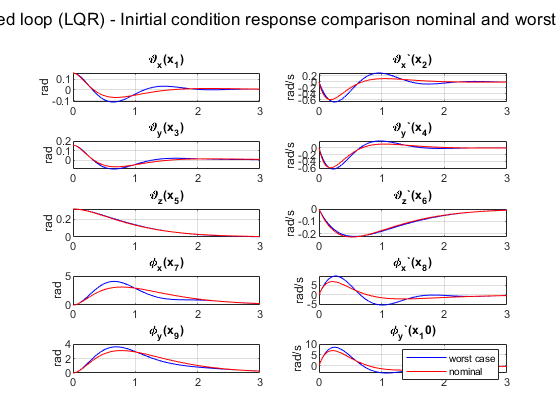

% initialplot
X0 = [pi/20 0 pi/20 0 pi/10 0 0 0 0 0]';
T_sim = 3; %sec=
initialplt(feedback(wcu.G,K_lqr),'b',X0,T_sim,110); 
initialplt(feedback(G_n,K_lqr),'r',X0,T_sim,110);
legend('worst case','nominal')
sgtitle('Closed loop (LQR) - Inirtial condition response comparison nominal and worst case')

#### Singular value plota

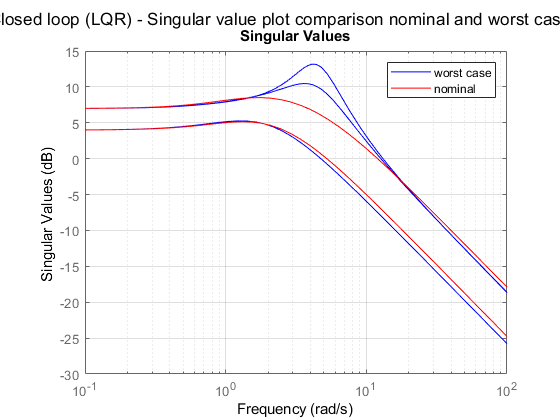

figure(111);
sigma(feedback(wcu.G,K_lqr),'b');
hold on;
sigma(feedback(G_n,K_lqr),'r');
legend('worst case','nominal')
grid on;
sgtitle('Closed loop (LQR) - Singular value plot comparison nominal and worst case')

## Validate worst case performance with the nonlinear model

Interesting is to see if nonlinear system is still stable for worst case parameters and LQR controller calculated for the nominal parameters.

% generate the worst  case parameters nonlinear model ans save it to  nlin_model_wcu function
model_generation_worst_case;

Creating a matlab function from nonlinear model
This may take few minutes
Writing function in the file
Elapsed time is 65.536188 seconds.



% Simulate and compare worst case linear and nonliner
initialplot_compare_nlin(@nlin_model_wcu,wcu.G,K_lqr,X0,T_sim,120,121)

nonlinear system simulation
Nonlinear simulation: 3.00 sec / 3.00 sec
Elapsed time is 28.691398 seconds.
lienar system simulation
Elapsed time is 0.049937 seconds.


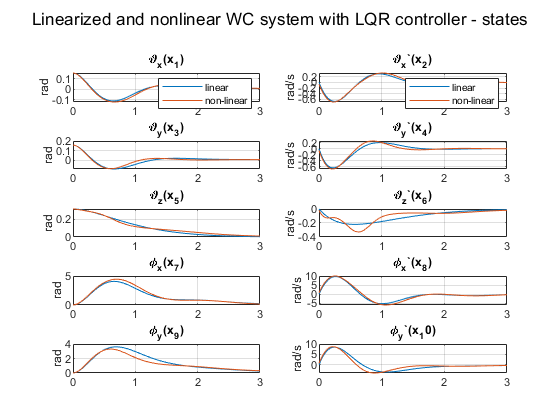

figure(120);
sgtitle('Linearized and nonlinear WC system with LQR controller - states')

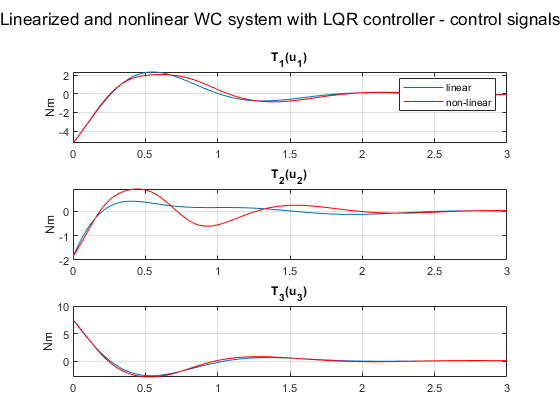

figure(121);
sgtitle('Linearized and nonlinear WC system with LQR controller - control signals')
drawnow

# Distrubance rejection and noise attenuation

#### **Ballbot has two type of disturbance **

 - ***force acting on the body - hunam interaction ****(w)*

 - ***measurement noise *** (*n*)

   > acceletometer and gyro

   > influences thetax, d_thetax, thetay, d_thetay  

#### ** Ballbot system**

 dx = Ax + [B_n B_w B_u]*[w n u]'

 y = Cx + [D_n D_w D_u]*[w n u]'

 u = K*x

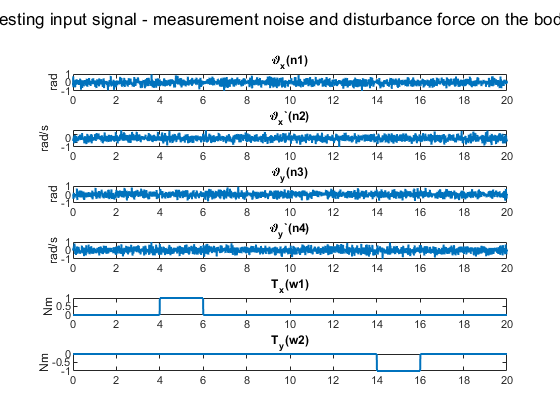

% definining the standardized testing input for distrubance rejection
t_d = linspace(0,20,2000);
N_d = length(t_d);
n = randn(4,N_d);
n = n/max(n(:));
wx = [zeros(1,0.2*N_d), ones(1,0.1*N_d), zeros(1,0.7*N_d)];
wy = [zeros(1,0.7*N_d), -ones(1,0.1*N_d) zeros(1,0.2*N_d)];
dist = [n; wx; wy];

figure(200);
state_var_names = {'\vartheta_x', '\vartheta_x`','\vartheta_y', '\vartheta_y`'};
for i = 1:4
    subplot(6,1,i);
    plot(t_d,dist(i,:),'LineWidth',1.5);
    hold on
    title(strcat(state_var_names{i},'(n',num2str(i),')'))
    if mod(i,2)
        ylabel('rad')
    else
        ylabel('rad/s')
    end
end
w_names={'T_x','T_y'};
for i = 1:2
    subplot(6,1,4+i);
    plot(t_d,dist(4+i,:),'LineWidth',1.5);
    hold on
    title(strcat(w_names{i},'(w',num2str(i),')'))
    ylabel('Nm')
end
sgtitle('Testing input signal - measurement noise and disturbance force on the body')

## Creating the factorial representaion

%% disturbance matrix
B_w = fW(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
% noise matrix
B_n = zeros(10,4);
% measurement noise variance 1 degree 
D_n = 0.5/180*pi*eye(10,4); 
% input D matrix
D_u = zeros(10,5);
C_z = [G_n.c; zeros(3,10)];
D_z = [D_n  D_u ; [zeros(3,6) 5*eye(3)]];
% model for h-infinity synthesis containing z output
Pz = ss(G_n.a, [B_n B_w G_n.b], [C_z; G_n.c], [ D_z; [D_n D_u] ]);
D_y = [D_n  D_u ; [zeros(3,6) eye(3)]];
% model for simulation using y as output
P = ss(G_n.a, [B_n B_w G_n.b], [C_z; G_n.c], [ D_y; [D_n D_u] ]);

% worst case model
% disturbance matrix
B_w_wcu = fW(rK_n, rW_n, rA_n, wcu.l, mAW_n, mK_n, wcu.A_ThetaAWx, wcu.A_ThetaAWy, wcu.A_ThetaAWz, wcu.ThetaKi, wcu.ThetaWi);
% model for h-infinity synthesis containing z output
Pz_wc = ss(wcu.G.a, [B_n B_w_wcu wcu.G.b], [C_z; wcu.G.c], [ D_z; [D_n D_u]]);
% model for simulation using y as output
P_wc = ss(wcu.G.a, [B_n B_w_wcu wcu.G.b], [C_z; wcu.G.c], [ D_y; [D_n D_u]]);

## Initial LQR disturbance rejection

Compariosn of linear and nonliner performcane using nominal and worst case parameters

% complarison linear nonlinear disturbance rejection
nlsim(@nlin_model_n,K_lqr,dist,t_d,P,201,202);

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 35.356981 seconds.


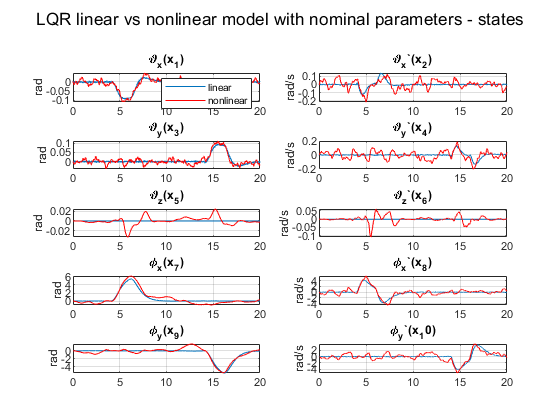

figure(201)
sgtitle('LQR linear vs nonlinear model with nominal parameters - states')

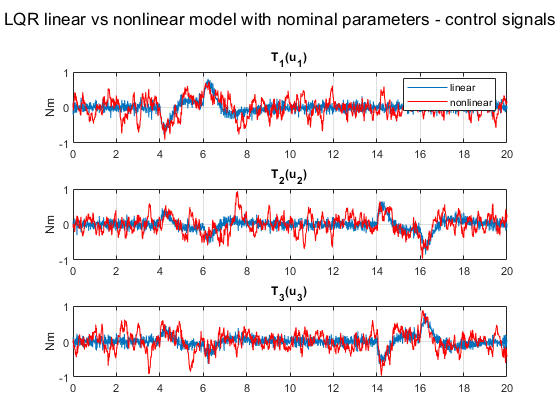

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 25.862673 seconds.


figure(202)
sgtitle('LQR linear vs nonlinear model with nominal parameters - control signals')
% complarison linear nonlinear disturbance rejection
nlsim(@nlin_model_wcu,K_lqr,dist,t_d,P_wc,203,204);

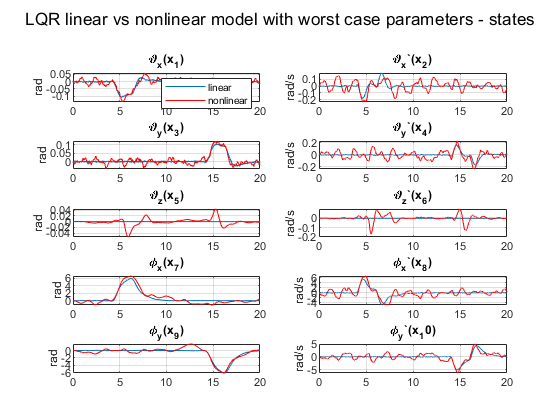

figure(203)
sgtitle('LQR linear vs nonlinear model with worst case parameters - states')

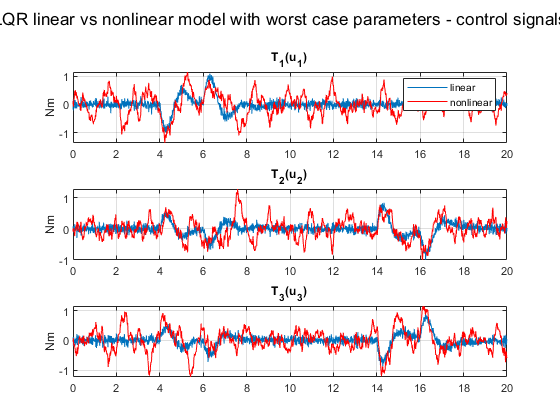

figure(204)
sgtitle('LQR linear vs nonlinear model with worst case parameters - control signals')

### Singular value plot for disturbance rejection fonominal and worst case model

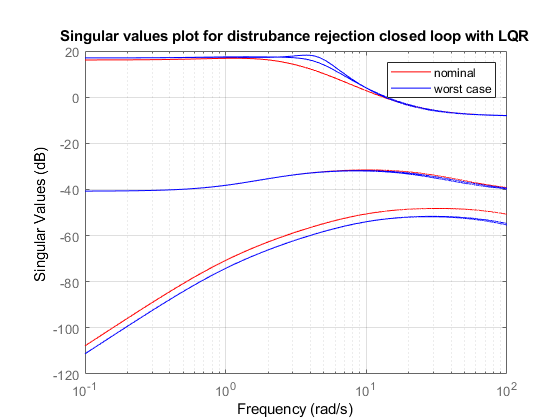

% plot singular values of distrurbance rejection loop
figure(301)
sigma(lft(P,-K_lqr),'r',lft(P_wc,-K_lqr),'b',(0.1:0.01:100));
legend('nominal','worst case');
grid on
title('Singular values plot for distrubance rejection closed loop with LQR')

## H-infinity controller design

Fixed structure - gain U=K*x;

%% H-infinity controller design fixed
% hinf fixed structure - gain
K_tun = realp('K_t',ones(3,10));   
K_tun.Minimum = -100*ones(3,10); 
K_tun.Maximum = 100*ones(3,10);
[C,gamma,info] = hinfstruct(Pz_wc,-K_tun);

Final: Peak gain = 7.31, Iterations = 302


K_hinf = C.Blocks.K_t.Value

K_hinf =   -28.2287  -61.1393   56.5199   32.1439   26.3552  -18.2795    2.1585   -3.3207   -1.2492    2.5740
  -35.2400  -75.5475  100.0000   49.5876   76.9363   -6.3722    6.8063   -3.5389   -4.3244    2.8175
  -41.5532  -99.9788  -98.6261  -13.1581   99.9999   -9.7817    8.8984   -4.6903   -7.9943   -0.3819


## **Comparison of H-infinity and LQR **

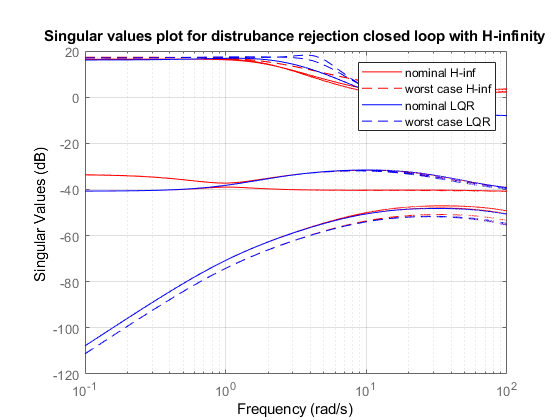

% plot singular values of distrurbance rejection loop
figure(302)
sigma(lft(P,-K_hinf),'r',lft(P_wc,-K_hinf),'--r',lft(P,-K_lqr),'b',lft(P_wc,-K_lqr),'--b',(0.1:0.01:100));
legend('nominal H-inf','worst case H-inf','nominal LQR','worst case LQR');
grid on
title('Singular values plot for distrubance rejection closed loop with H-infinity')

## Complarison H-infinity and LQR linear models

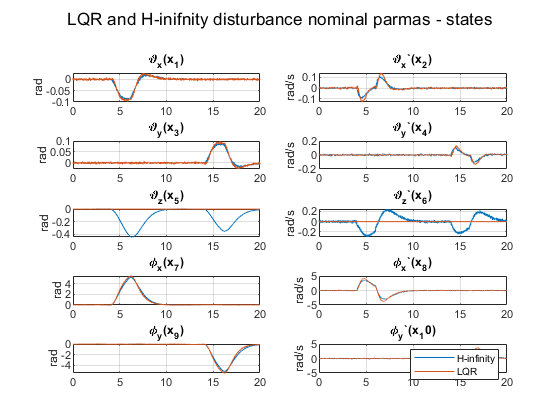

linsim(lft(P,-K_hinf),'b',dist,t_d,303,304);
linsim(lft(P,-K_lqr),'r',dist,t_d,303,304);
figure(303)
sgtitle('LQR and H-inifnity disturbance nominal parmas - states')
legend('H-infinity','LQR')

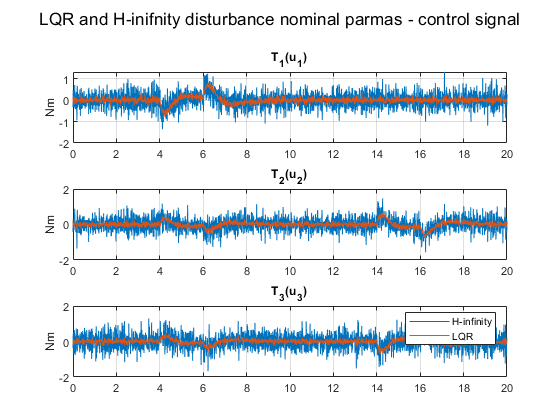

figure(304)
sgtitle('LQR and H-inifnity disturbance nominal parmas - control signal')
legend('H-infinity','LQR')

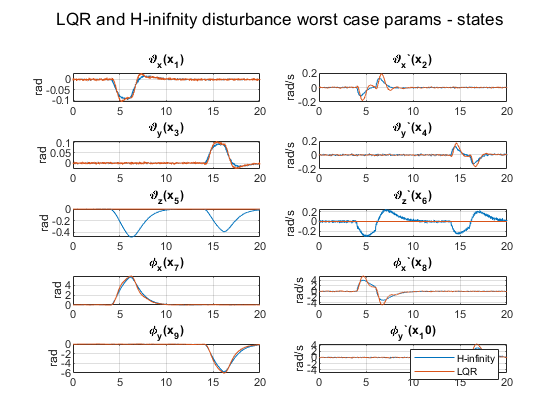

linsim(lft(P_wc,-K_hinf),'b',dist,t_d,305,306);
linsim(lft(P_wc,-K_lqr),'r',dist,t_d,305,306);
figure(305)
sgtitle('LQR and H-inifnity disturbance worst case params - states')
legend('H-infinity','LQR')

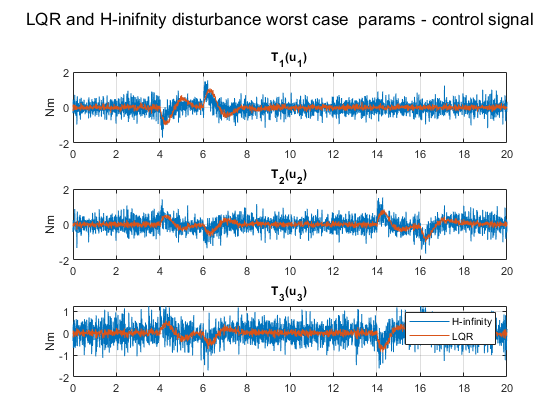

figure(306)
sgtitle('LQR and H-inifnity disturbance worst case  params - control signal')
legend('H-infinity','LQR')

### Bode diagram of comparison 

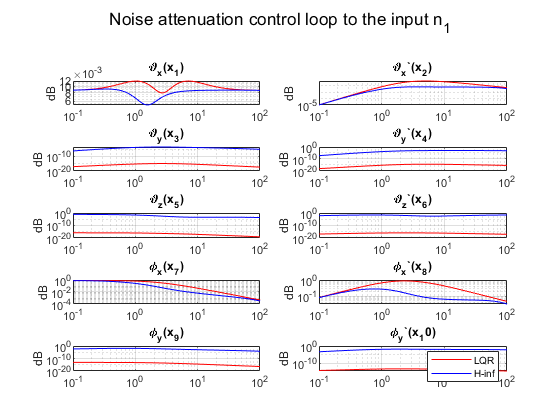

H_lqr = lft(P,-K_lqr);
H_hinf = lft(P,-K_hinf);
bodemg(H_lqr(1:10,1),'r',311);
hold on
bodemg(H_hinf(1:10,1),'b',311);
legend('LQR', 'H-inf')
sgtitle('Noise attenuation control loop to the input n_1');

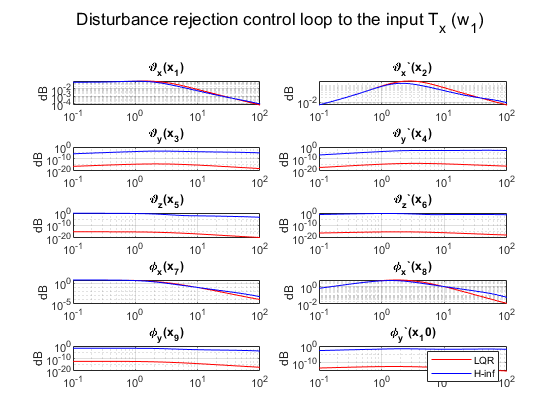


bodemg(H_lqr(1:10,5),'r',312);
hold on
bodemg(H_hinf(1:10,5),'b',312);
legend('LQR', 'H-inf')
sgtitle('Disturbance rejection control loop to the input T_x (w_1)');

## Complarison H-infinity and nonlinear model

nlsim(@nlin_model_wcu,K_hinf,dist,t_d,P_wc,307,308);

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 37.401250 seconds.


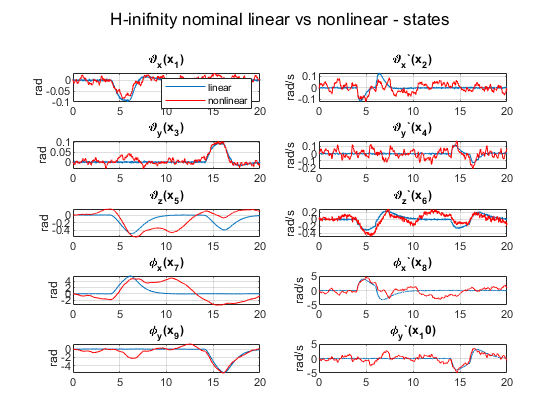

figure(307);
sgtitle('H-inifnity nominal linear vs nonlinear - states')

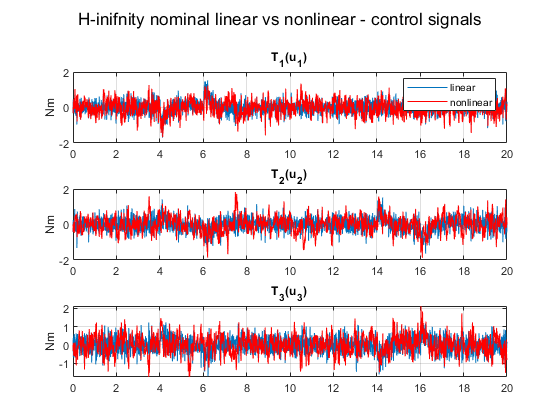

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 40.492764 seconds.


figure(308)
sgtitle('H-inifnity nominal linear vs nonlinear - control signals')
nlsim(@nlin_model_n,K_hinf,dist,t_d,P,309,310);

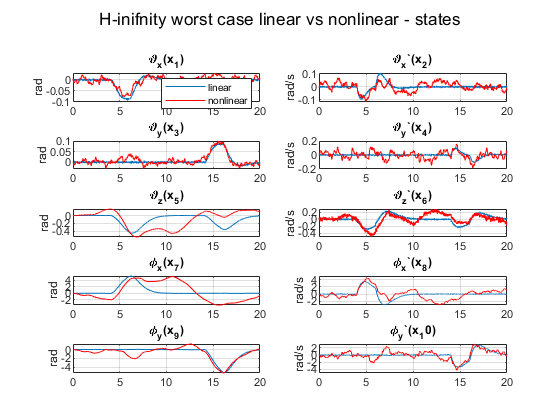

figure(309)
sgtitle('H-inifnity worst case linear vs nonlinear - states')

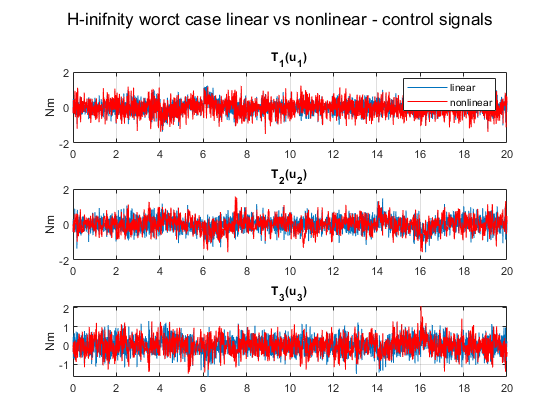

figure(310)
sgtitle('H-inifnity worct case linear vs nonlinear - control signals')

## State space H-infinity controller 

State space controller

%% H-infinity controller design not fixed
%% hinf controller general
nmeas = 10;
ncont = 3;
opts = hinfsynOptions('Display','on','LimitGain','on');
[K_hinf_ss,CL,gamma,info] = hinfsyn(Pz,nmeas,ncont,opts);


  Test bounds:  0.12 <=  gamma  <=  10.2

   gamma        X>=0        Y>=0       rho(XY)<1    p/f
  1.11e+00    -2.0e+02 #   5.0e-20     6.822e-09     f
  3.36e+00    -3.2e+03 #   5.0e-20     7.368e-10     f
  5.86e+00     1.5e-01     5.0e-20     6.840e-05     p
  4.44e+00    -1.3e+04 #   5.0e-20     4.228e-10     f
  5.10e+00     1.5e-01     5.0e-20     3.290e-03     p
  4.76e+00    -2.9e+04 #   5.0e-20     3.680e-10     f
  4.92e+00    -6.3e+04 #   5.0e-20     3.433e-10     f
  5.01e+00    -1.4e+05 #   5.0e-20     3.316e-10     f
  5.05e+00    -3.9e+05 #   5.0e-20     3.259e-10     f
  Limiting gains...
  5.10e+00     1.5e-01     5.0e-19     1.896e-02     p
  5.10e+00     1.5e-01     4.7e-18     5.514e-02     p
  5.10e+00     1.5e-01     1.6e-17     1.496e-01     p
  5.10e+00     1.5e-01     4.0e-17     1.106e+00 #   f

  Best performance (actual): 5.1


K_hinf_ss


K_hinf_ss =
 
  A = 
                x1          x2          x3          x4          x5
   x1   -2.392e-07           1   4.155e-12   1.569e-12  -2.181e-05
   x2        -2752      -896.7  -2.461e-09  -7.988e-10  -4.494e-06
   x3   -2.588e-12  -4.626e-13  -2.082e-07           1   2.598e-05
   x4    3.733e-09   1.212e-09       -2752      -896.7   9.539e-06
   x5    6.337e-21   1.177e-21    3.57e-23     2.4e-23     -0.0635
   x6    3.843e-11   1.248e-11   2.786e-11   9.045e-12      -1.158
   x7     5.75e-11   1.202e-10  -8.312e-17  -3.139e-17   4.394e-10
   x8    4.021e+04   1.306e+04   3.605e-08    1.17e-08   2.188e-06
   x9    1.188e-16   2.125e-17    6.23e-11   4.883e-10  -1.219e-09
   x10  -5.442e-08  -1.767e-08   4.021e+04   1.306e+04  -5.462e-06
 
                x6          x7          x8          x9         x10
   x1   -5.655e-05       3.908       410.8  -5.244e-05    -0.00376
   x2   -1.072e-05      -27.94   2.417e+04  -9.382e-06  -0.0006728
   x3    0.0001371   3.557e-06    0.00

## Comparison LQR and H-inifnity state space

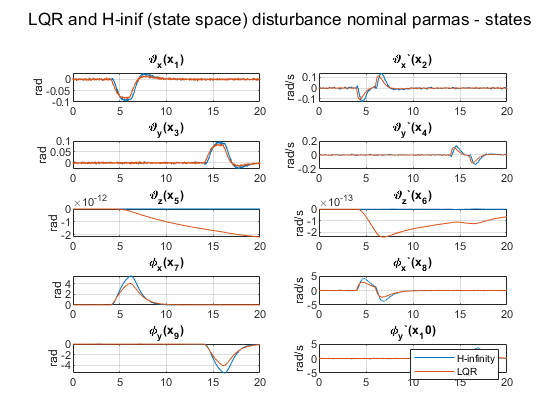

linsim(lft(P,-K_lqr),'b',dist,t_d,404,405);
linsim(lft(P,K_hinf_ss),'r',dist,t_d,404,405);
figure(404)
sgtitle('LQR and H-inif (state space) disturbance nominal parmas - states')
legend('H-infinity','LQR')

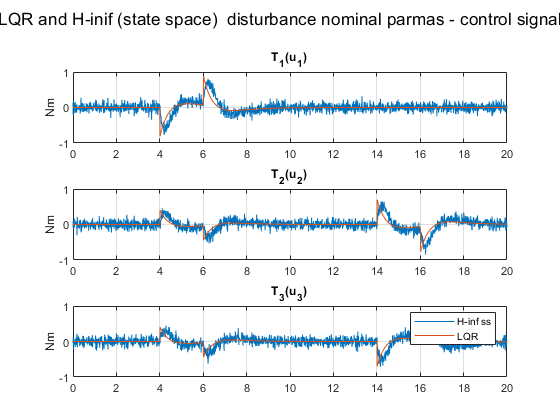

figure(405)
sgtitle('LQR and H-inif (state space)  disturbance nominal parmas - control signal')
legend('H-inf ss','LQR')

## Bode diagram of LQR, H-infinity gain and H-infinity state space

We can see that state space H-infinity controller has lowest gain for almost all the transfrer functions on the plot making it the most robustly stable one.

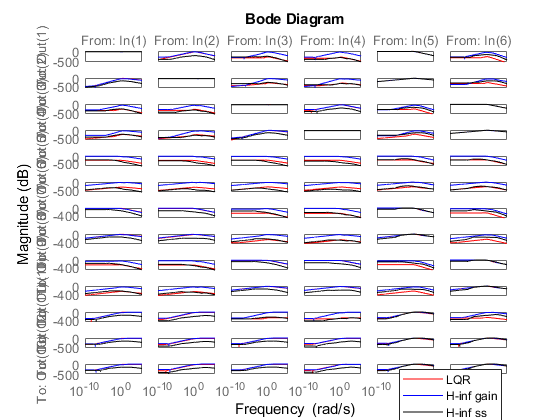

figure(406)
bodemag(lft(P,-K_lqr),'r',lft(P,-K_hinf), 'b',lft(P,K_hinf_ss),'k');
legend('LQR','H-inf gain','H-inf ss');

## H-infintiy norms for nominal and worst case parameter linear model comparison of LQR, fixed H-inifnity and state space H-Infinity controller

hinfnorm(lft(P,-K_lqr))

ans = 6.9632

hinfnorm(lft(P,-K_hinf))

ans = 6.7143

hinfnorm(lft(P,K_hinf_ss))

ans = 5.1048


hinfnorm(lft(P_wc,-K_lqr))

ans = 8.1157

hinfnorm(lft(P_wc,-K_hinf))

ans = 7.3090

hinfnorm(lft(P_wc,K_hinf_ss))

ans = Inf

## Closed loop singular value plot comparison

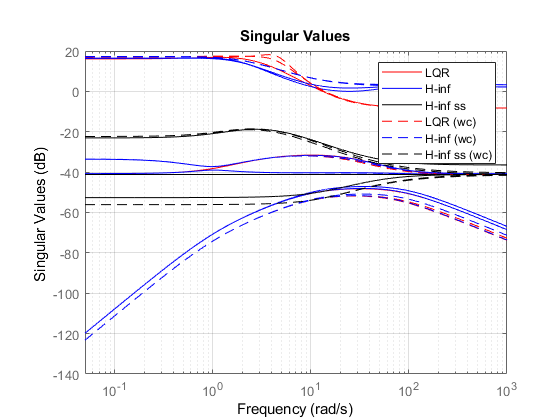

% plot singular values of distrurbance rejection loop
figure(407)
sigma(lft(P,-K_lqr),'r',lft(P,-K_hinf),'b',lft(P,-K_hinf_ss),'k',lft(P_wc,-K_lqr),'--r',lft(P_wc,-K_hinf),'--b',lft(P_wc,-K_hinf_ss),'--k',(0.05:0.01:1000));
legend('LQR','H-inf','H-inf ss','LQR (wc)','H-inf (wc)','H-inf ss (wc)');
grid on;